# **Computer Assignment 3 **

`Signals and Symstems`

## **Erfan Panahi     **SID:810198369

# Part 1:.

- **Problem 1-0:**

fs = 20;
Ts = 1 / fs;
t = 0:Ts:1-Ts;
N = length(t);
f = -fs/2:fs/N:fs/2-fs/N;

## 
$$x_1 {\left(t\right)}=e^{j2\pi {\left(5\right)}t} +e^{j2\pi {\left(8\right)}t}$$


x01 = exp(1j*2*pi*5*t)+exp(1j*2*pi*8*t);
x01f = fftshift(fft(x01));
x01f = x01f/max(abs(x01f));
plot(f,abs(x01f),'r');

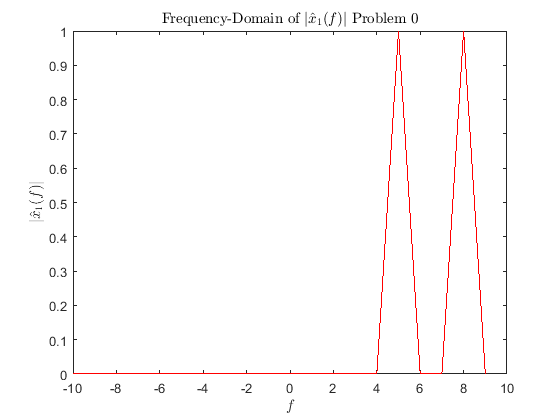

title('Frequency-Domain of $ \left|\hat{x}_{1}(f)\right|$ Problem 0','Interpreter','latex');
xlabel('$f$','Interpreter','latex');
ylabel('$ \left|\hat{x}_{1}(f)\right|$','Interpreter','latex');

## 
$$x_2 {\left(t\right)}=e^{j2\pi {\left(5\right)}t} +e^{j2\pi {\left(5.1\right)}t}$$


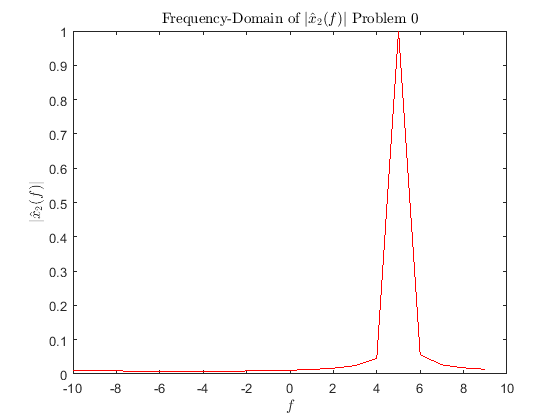

x02 = exp(1j*2*pi*5*t)+exp(1j*2*pi*5.1*t);
x02f = fftshift(fft(x02));
x02f = x02f/max(abs(x02f));
plot(f,abs(x02f),'r');
title('Frequency-Domain of $ \left|\hat{x}_{2}(f)\right|$ Problem 0','Interpreter','latex');
xlabel('$f$','Interpreter','latex');
ylabel('$ \left|\hat{x}_{2}(f)\right|$','Interpreter','latex');

- **Problem 1-1:**

## 
$$x_1 {\left(t\right)}=\cos {\left(10\pi t\right)}$$


`Part a: ``Time-Domain of `$x_1 \left(t\right)$

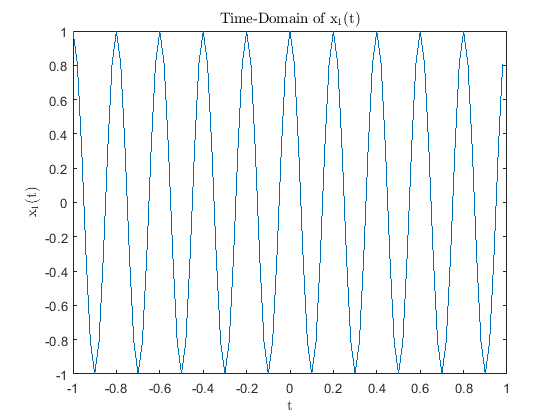

fs = 50;
Ts = 1 / fs;
t = -1:Ts:1-Ts;
N = length(t);
x1 = cos(10*pi*t);
plot(t,x1);
title('Time-Domain of x$_{1}$(t)','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('x$_{1}$(t)','Interpreter','latex');

`Part b: ``Frequency-Domain of `$\left.|\hat{x_1 \left(\right.} f\right)|$

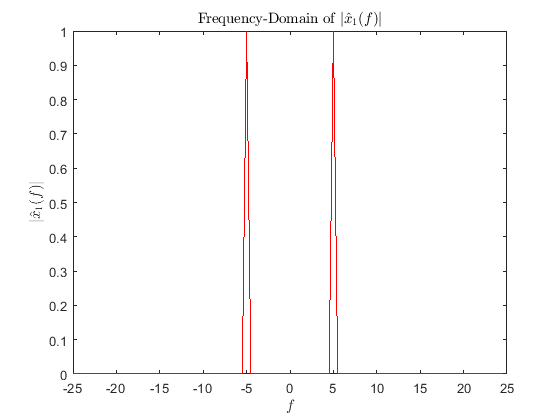

f = -fs/2:fs/N:fs/2-fs/N;
x1f = fftshift(fft(x1));
x1f = x1f/max(abs(x1f));
plot(f,abs(x1f),'r');
title('Frequency-Domain of $ \left|\hat{x}_{1}(f)\right|$','Interpreter','latex');
xlabel('$f$','Interpreter','latex');
ylabel('$ \left|\hat{x}_{1}(f)\right|$','Interpreter','latex');

`Part c: ``Find the` `Fourier transform in theory`


$$f=\frac{10\pi }{2\pi }=5\to f_k =5k$$



$$x_1 {\left(t\right)}=\cos {\left(10\pi t\right)}=\cos {\left(2\pi ft\right)}=\frac{1}{2}e^{-j10\pi t} +\frac{1}{2}e^{j10\pi t} \to a_1 =a_{-1} =\frac{1}{2} ,  a_k =0 \left(k\not= 1\ldotp -1\right)$$



$$\hat{x_1 } {\left(f\right)}=\sum_k a_k \delta \left(f-f_k \right)=\frac{1}{2}\delta {\left(f-5\right)}+\frac{1}{2}\delta \left(f+5\right)$$



$$\to {\left|\hat{x_1 } {\left(f\right)}\right|}=\frac{1}{2}\delta {\left(f-5\right)}+\frac{1}{2}\delta \left(f+5\right)$$


- **Problem 1-2:**

## 
$$x_2 {\left(t\right)}=\Pi \left(t\right)$$


`Part a: ``Time-Domain of `$x_2 \left(t\right)$

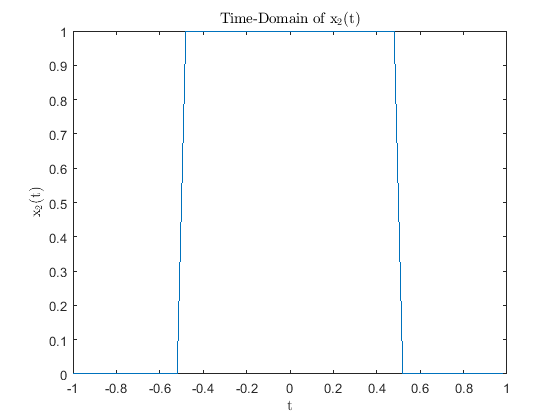

fs = 50;
Ts = 1 / fs;
t = -1:Ts:1-Ts;
N = length(t);
x2 = rectangularPulse(t);
plot(t,x2);
title('Time-Domain of x$_{2}$(t)','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('x$_{2}$(t)','Interpreter','latex');

`Part b: ``Frequency-Domain of `$\left|\left.\hat{x_2 \left(\right.} f\right)\right|$

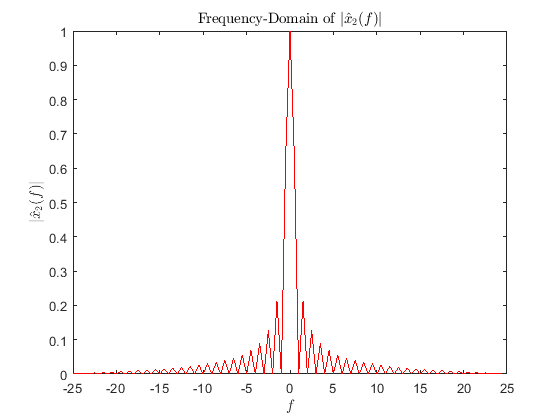

f = -fs/2:fs/N:fs/2-fs/N;
x2f = fftshift(fft(x2));
x2f = x2f/max(abs(x2f));
plot(f,abs(x2f),'r');
title('Frequency-Domain of $ \left|\hat{x}_{2}(f)\right|$','Interpreter','latex');
xlabel('$f$','Interpreter','latex');
ylabel('$ \left|\hat{x}_{2}(f)\right|$','Interpreter','latex');

`Part c: ``Find the` `Fourier transform in theory`


$$x_2 {\left(t\right)}=\Pi {\left(t\right)}\to \hat{x_2 } {\left(f\right)}=\int_{-\infty }^{+\infty } \Pi {\left(t\right)}e^{-j2\pi ft} dt=\int_{-\frac{1}{2}}^{\frac{1}{2}} e^{-j2\pi ft} dt=\frac{1}{-j2\pi f}\left(e^{-j\pi f} -e^{j\pi f} \right)= \frac{\mathrm{s}\mathrm{i}\mathrm{n}{\left(\pi f\right)}}{\pi f}=sinc\left(f\right)$$



$$\to {\left|\hat{x_2 } {\left(f\right)}\right|}=\left|sinc{\left(f\right)}\left|\right.$$


- **Problem 1-3:**

## 
$$x_3 {\left(t\right)}=\Pi \left(t\right)\cos {\left(10\pi t\right)}$$


`Part a: ``Time-Domain of `$x_3 \left(t\right)$

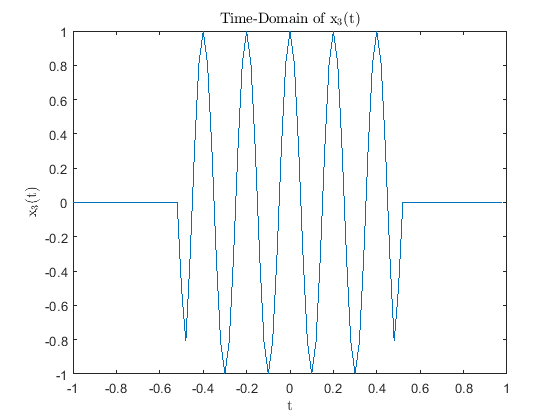

fs = 50;
Ts = 1 / fs;
t = -1:Ts:1-Ts;
N = length(t);
x3 = x1.*x2;
plot(t,x3);
title('Time-Domain of x$_{3}$(t)','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('x$_{3}$(t)','Interpreter','latex');

`Part b: ``Frequency-Domain of `$\left|\left.\hat{x_3 \left(\right.} f\right)\right|$

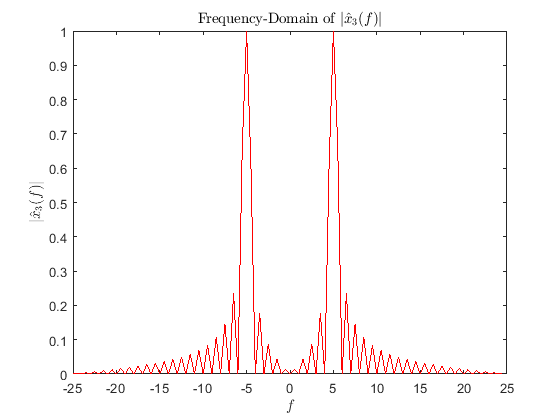

f = -fs/2:fs/N:fs/2-fs/N;
x3f = fftshift(fft(x3));
x3f = x3f/max(abs(x3f));
plot(f,abs(x3f),'r');
title('Frequency-Domain of $ \left|\hat{x}_{3}(f)\right|$','Interpreter','latex');
xlabel('$f$','Interpreter','latex');
ylabel('$ \left|\hat{x}_{3}(f)\right|$','Interpreter','latex');

`Part c: ``Find the` `Fourier transform in theory`


$$x_3 {\left(t\right)}=\Pi {\left(t\right)}\cos {\left(10\pi t\right)}\to \hat{x_3 } {\left(f\right)}={\left(\hat{x_1 } {\left(f\right)}*\hat{x_2 } {\left(f\right)}\right)}$$



$$\to \hat{x_3 } {\left(f\right)}=\int_{-\infty }^{+\infty } {\left(\hat{x_1 } {\left(\rho \right)}\hat{x_2 } {\left(f-\rho \right)}\right)}d\rho =\int_{-\infty }^{+\infty } {\left(\frac{1}{2}\delta {\left(\rho -5\right)}+\frac{1}{2}\delta \left(\rho +5\right)\right)sinc{\left(f-\rho \right)}\right)}d\rho =\frac{1}{2}{\left(sinc{\left(f+5\right)}+sinc{\left(f-5\right)}\right)}$$



$$\to {\left|\hat{x_3 } {\left(f\right)}\right|}=\frac{1}{2}{\left|sinc{\left(f+5\right)}+sinc{\left(f-5\right)}\right|}$$


- **Problem 1-4:**

## 
$$x_4 {\left(t\right)}=\cos {\left(30\pi t+\frac{\pi }{4}\right)}$$


`Part a: ``Frequency-Domain of `$\left|\left.\hat{x_4 \left(\right.} f\right)\right|$

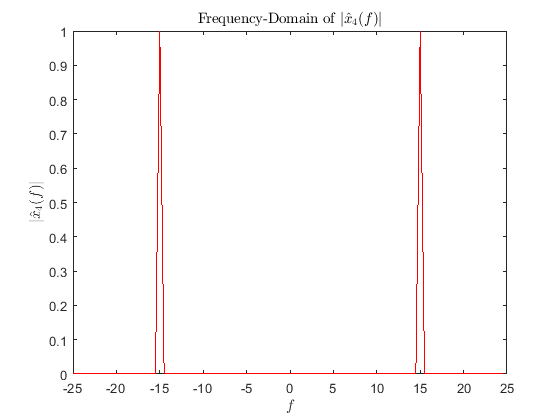

fs = 50;
Ts = 1 / fs;
t = -1:Ts:1-Ts;
N = length(t);
f = -fs/2:fs/N:fs/2-fs/N;
x4 = cos(30*pi*t+pi/4);
x4f = fftshift(fft(x4));
x4f = x4f/max(abs(x4f));
plot(f,abs(x4f),'r');
title('Frequency-Domain of $ \left|\hat{x}_{4}(f)\right|$','Interpreter','latex');
xlabel('$f$','Interpreter','latex');
ylabel('$ \left|\hat{x}_{4}(f)\right|$','Interpreter','latex');

`Part b: ``Frequency-Domain of `$\left.\angle \hat{x_4 \left(\right.} f\right)$

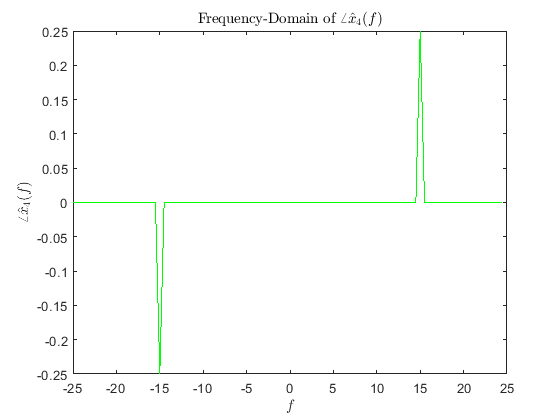

to1=1e-6;
x4f(abs(x4f)<to1)=0;
theta=angle(x4f);
plot(f,theta/pi,'g');
title('Frequency-Domain of $ \angle\hat{x}_{4}(f)$','Interpreter','latex');
xlabel('$f$','Interpreter','latex');
ylabel('$ \angle\hat{x}_{4}(f)$','Interpreter','latex');

`Part c: ``Find the` `Fourier transform in theory`


$$f=\frac{30\pi }{2\pi }=15\to f_k =15k$$



$$x_4 {\left(t\right)}=\cos {\left(30\pi t+\frac{\pi }{4}\right)}=\cos {\left(2\pi ft+\frac{\pi }{4}\right)}=\frac{1}{2}e^{-j{\left(30\pi t+\frac{\pi }{4}\right)}} +\frac{1}{2}e^{j{\left(30\pi t+\frac{\pi }{4}\right)}} =\frac{1}{2}e^{-j\frac{\pi }{4}} e^{-j30\pi t} +\frac{1}{2}e^{j\frac{\pi }{4}} e^{j30\pi t} \to a_1 =\frac{1}{2}e^{j\frac{\pi }{4}} ,  a_{-1} =\frac{1}{2}e^{-j\frac{\pi }{4}} ,  a_k =0 \left(k\not= 1\ldotp -1\right)$$



$$\hat{x_4 } {\left(f\right)}=\sum_k a_k \delta \left(f-f_k \right)=\frac{1}{2}e^{j\frac{\pi }{4}} \delta {\left(f-15\right)}+\frac{1}{2}e^{-j\frac{\pi }{4}} \delta \left(f+15\right)$$



$$\to {\left|\hat{x_4 } {\left(f\right)}\right|}=\frac{1}{2}\delta {\left(f-15\right)}+\frac{1}{2}\delta {\left(f+15\right)}$$



$$\to ∡\hat{x_4 } {\left(f\right)}={\left\{\begin{array}{c}
\frac{\pi }{4},  f=15\\
-\frac{\pi }{4},  f=-15\\
0,  o\ldotp w\ldotp 
\end{array}\right)}$$


- **Problem 1-5:**

## 
$$x_5 {\left(t\right)}=\sum_{k=-9}^9 \Pi {\left(t-2k\right)}$$


`Part a: ``Time-Domain of `$x_4 \left(t\right)$

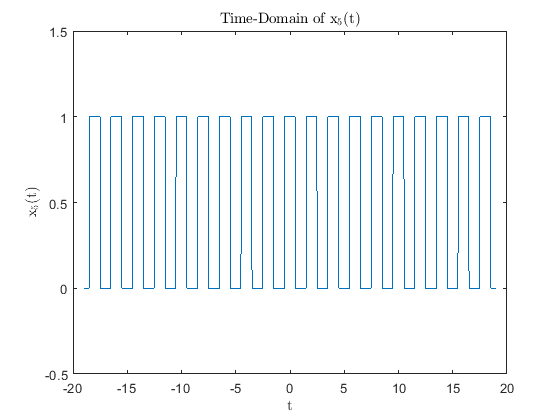

fs = 50;
Ts = 1 / fs;
t = -19:Ts:19-Ts;
N = length(t);
x5 = square((t+0.5)*pi); %square generate a square wave with domain -1 to 1 
x5 = (x5+1)/2;%scaling domain for 0 to 1
plot(t,x5);
title('Time-Domain of x$_{5}$(t)','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('x$_{5}$(t)','Interpreter','latex');
ylim([-0.5 1.5]);

`Part b: ``Frequency-Domain of `$\left|\left.\hat{x_4 \left(\right.} f\right)\right|$

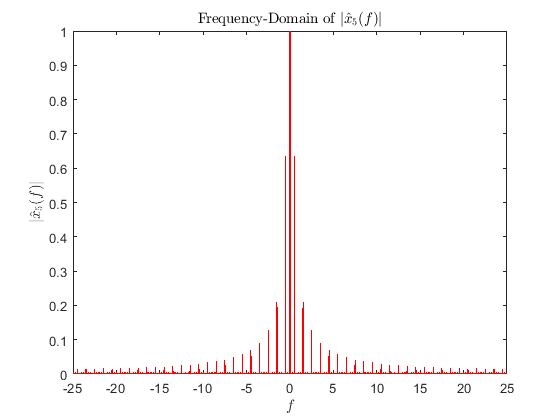

f = -fs/2:fs/N:fs/2-fs/N;
x5f = fftshift(fft(x5));
x5f = x5f/max(abs(x5f));
plot(f,abs(x5f),'r');
title('Frequency-Domain of $ \left|\hat{x}_{5}(f)\right|$','Interpreter','latex');
xlabel('$f$','Interpreter','latex');
ylabel('$ \left|\hat{x}_{5}(f)\right|$','Interpreter','latex');

`Part c: ``Find the` `Fourier transform in theory`


$$T=2\to f=\frac{1}{T}=\frac{1}{2}=\to f_k =\frac{k}{2}$$



$$x_5 {\left(t\right)}=\sum_{k=-\infty }^{\infty } \Pi {\left(t-2k\right)}\to  a_0 =\frac{1}{2},  a_k {\left(k\not= 0\right)}=\frac{1}{2}sinc{\left(\frac{k}{2}\right)}$$



$$\hat{x_5 } {\left(f\right)}=\sum_k a_k \delta \left(f-f_k \right)=\frac{1}{2}\delta {\left(f\right)}+\sum_k \frac{1}{2}sinc{\left(\frac{k}{2}\right)}\delta \left(f-\frac{k}{2}\right)$$



$${\left|\hat{x_5 } {\left(f\right)}\right|}=\frac{1}{2}\delta {\left(f\right)}+\frac{1}{2}\sum_k {\left|sinc{\left(\frac{k}{2}\right)}\right|}\delta \left(f-\frac{k}{2}\right)$$


`or`


$$x_5 {\left(t\right)}=\sum_{k=-9}^9 \Pi {\left(t-2k\right)}\to \hat{x_5 } {\left(f\right)}=\sum_{k=-9}^9 e^{-j4\pi fk} sinc\left(f\right)=sinc{\left(f\right)}+2\sum_{k=1}^9 \cos {\left(4\pi fk\right)}sinc\left(f\right)$$


|$\hat{x_5 } {\left(f\right)}|=sinc{\left(f\right)}+2\sum_{k=1}^9 |\cos {\left(4\pi fk\right)}|sinc\left(f\right)$

# Part 2:.

- **Problem 2-1:**

## 
$$x_6 {\left(t\right)}=\delta \left(t\right)$$


`Part a: ``Time-Domain of `$x_6 \left(t\right)$

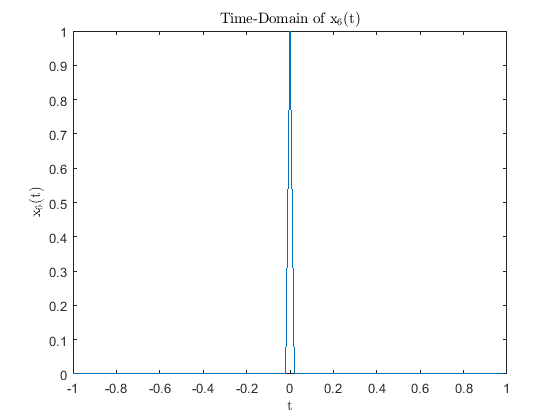

fs = 50;
Ts = 1 / fs;
t = -1:Ts:1-Ts;
N = length(t);
x6 = dirac(t)>0;
plot(t,x6);
title('Time-Domain of x$_{6}$(t)','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('x$_{6}$(t)','Interpreter','latex');

`Part b: ``Frequency-Domain of `$\left|\left.\hat{x_6 \left(\right.} f\right)\right|$

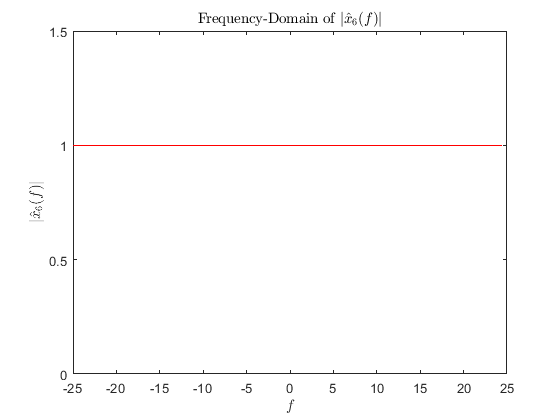

f = -fs/2:fs/N:fs/2-fs/N;
x6f = fftshift(fft(x6));
x6f = x6f/max(abs(x6f));
plot(f,abs(x6f),'r');
title('Frequency-Domain of $ \left|\hat{x}_{6}(f)\right|$','Interpreter','latex');
xlabel('$f$','Interpreter','latex');
ylabel('$ \left|\hat{x}_{6}(f)\right|$','Interpreter','latex');
ylim([0 1.5]);

`Part c: ``Find the` `Fourier transform in theory`


$$x_6 {\left(t\right)}=\delta {\left(t\right)}\to \hat{x_6 } {\left(f\right)}=\int_{-\infty }^{+\infty } \delta {\left(t\right)}e^{-j2\pi ft} dt=e^{-j2\pi f0} =e^0 =1$$



$$\to {\left|\hat{x_6 } {\left(f\right)}\right|}=1$$


- **Problem 2-2:**

## 
$$x_7 {\left(t\right)}=1$$


`Part a: ``Time-Domain of `$x_7 \left(t\right)$

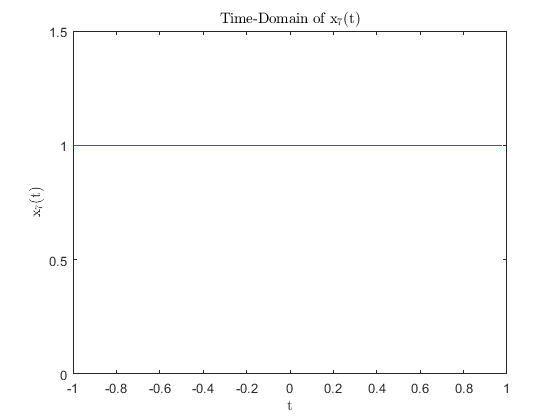

fs = 50;
Ts = 1 / fs;
t = -1:Ts:1-Ts;
N = length(t);
x7= ones(1,N); 
plot(t,x7);
title('Time-Domain of x$_{7}$(t)','Interpreter','latex');
xlabel('t','Interpreter','latex');
ylabel('x$_{7}$(t)','Interpreter','latex');
ylim([0 1.5]);

`Part b: ``Frequency-Domain of `$\left|\left.\hat{x_7 \left(\right.} f\right)\right|$

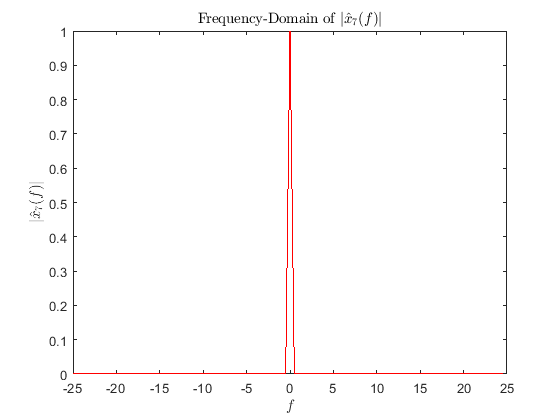

f = -fs/2:fs/N:fs/2-fs/N;
x7f = fftshift(fft(x7));
x7f = x7f/max(abs(x7f));
plot(f,abs(x7f),'r');
title('Frequency-Domain of $ \left|\hat{x}_{7}(f)\right|$','Interpreter','latex');
xlabel('$f$','Interpreter','latex');
ylabel('$ \left|\hat{x}_{7}(f)\right|$','Interpreter','latex');

`Part c: ``Find the` `Fourier transform in theory`


$$\begin{array}{l}
x_7 {\left(t\right)}=1\to \hat{x_7 } {\left(f\right)}=\int_{-\infty }^{+\infty } 1e^{-j2\pi ft} dt=\delta \left(f\right)\\
\to {\left|\hat{x_7 } {\left(f\right)}\right|}=\delta \left(f\right)
\end{array}$$
